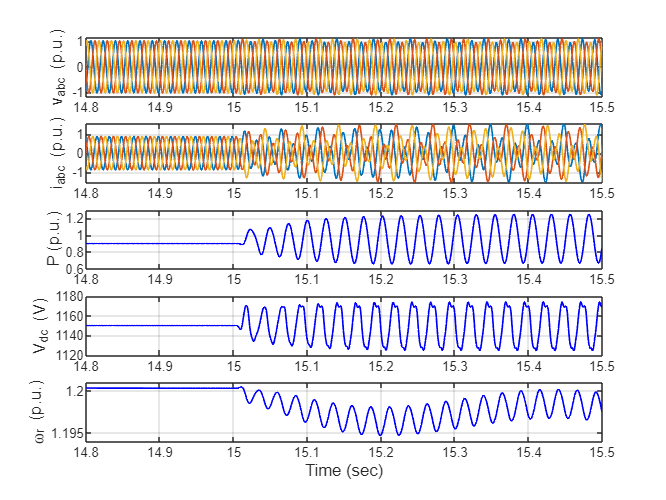

clear
clc

load dfig_data.mat

tout = 0:Ts:30;

figure
subplot(5,1,1)
plot(tout,simout(:,1),'LineWidth',1); hold on;
plot(tout,simout(:,2),'LineWidth',1); 
plot(tout,simout(:,3),'LineWidth',1); grid on;
ylabel('v_{abc} (p.u.)','FontSize',10);
xlim([14.8 15.5]);
ylim([-1.15 1.15]);

subplot(5,1,2)
plot(tout,simout(:,4),'LineWidth',1);hold on;
plot(tout,simout(:,5),'LineWidth',1);
plot(tout,simout(:,6),'LineWidth',1);grid on;
ylabel('i_{abc} (p.u.)','FontSize',10); 
xlim([14.8 15.5]);
ylim([-1.55 1.55]);

subplot(5,1,3)
plot(tout,simout(:,7),'b','LineWidth',1);
ylabel('P (p.u.)','FontSize',10); grid on;
xlim([14.8 15.5]);
ylim([0.6 1.3]);

subplot(5,1,4)
plot(tout,simout(:,8),'b','LineWidth',1); grid on;
ylabel('V_{dc} (V)','FontSize',10);
xlim([14.8 15.5]);
ylim([1120 1180]);

subplot(5,1,5)
plot(tout,simout(:,9),'b','LineWidth',1); grid on;
ylabel('\omega_{r} (p.u.)','FontSize',10); 
xlabel('Time (sec)','FontSize',10);
xlim([14.8 15.5]);
ylim([1.194 1.201]);

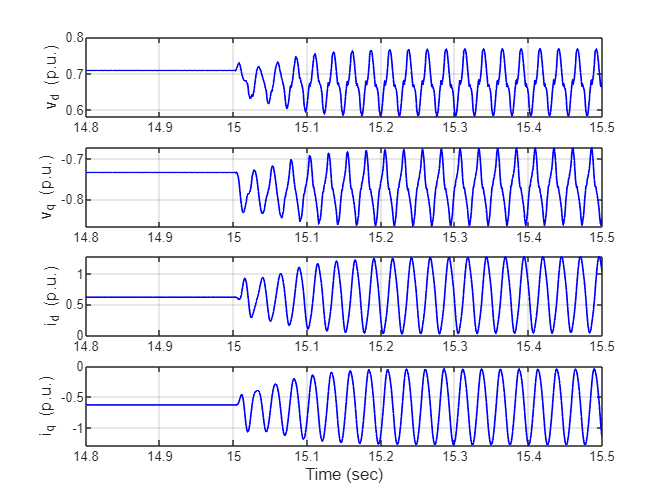

clear
clc

load dfig_dq.mat

tout = 0:Ts:30;

figure
subplot(4,1,1)
plot(tout,simout_dq(:,1),'b','LineWidth',1); grid on;
ylabel('v_{d} (p.u.)','FontSize',10);
xlim([14.8 15.5]);
% ylim([-1.15 1.15]);

subplot(4,1,2)
plot(tout,simout_dq(:,2),'b','LineWidth',1);grid on;
ylabel('v_{q} (p.u.)','FontSize',10); 
xlim([14.8 15.5]);
% ylim([-1.55 1.55]);

subplot(4,1,3)
plot(tout,simout_dq(:,3),'b','LineWidth',1);grid on;
ylabel('i_{d} (p.u.)','FontSize',10); 
xlim([14.8 15.5]);
% ylim([0.6 1.3]);

subplot(4,1,4)
plot(tout,simout_dq(:,4),'b','LineWidth',1); grid on;
ylabel('i_{q} (p.u.)','FontSize',10);
xlabel('Time (sec)','FontSize',10);
xlim([14.8 15.5]);

% ylim([1120 1180]);

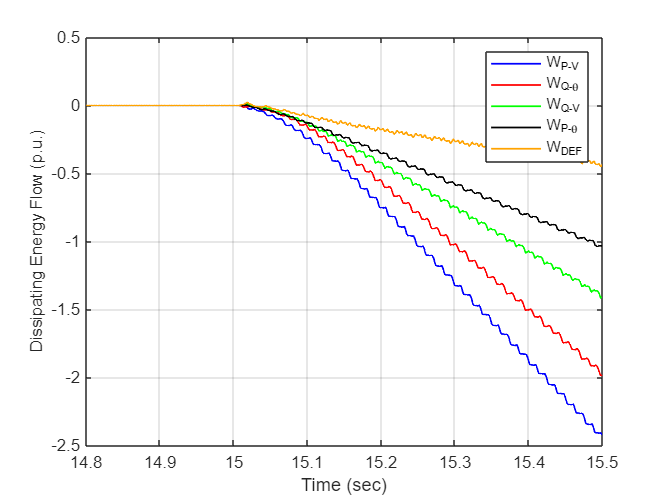

load de_data.mat
figure
plot(tout,simout1(:,1),'b','LineWidth',1);hold on;
plot(tout,simout1(:,2),'r','LineWidth',1)
plot(tout,simout1(:,3),'g','LineWidth',1)
plot(tout,simout1(:,4),'k','LineWidth',1)
plot(tout,simout1(:,5),'color','#FFA300','LineWidth',1);grid on;
legend('W_{P-V}','W_{Q-\theta}','W_{Q-V}','W_{P-\theta}','W_{DEF}');
xlim([14.8 15.5]);
ylabel('Dissipating Energy Flow (p.u.)','FontSize',10);
xlabel('Time (sec)');